# Plot Gas Prices

This interaction is not graded. You can move to the next section when you are ready.

countries = string(table2array(readtable("../data/gPrices.xlsx", "Sheet", "countries", "ReadVariableNames", false)));
prices = table2array(readtable("../data/gPrices.xlsx", "Sheet", "prices", "ReadVariableNames", false));
Year = table2array(readtable("../data/gPrices.xlsx", "Sheet", "Year", "ReadVariableNames", false));
whos

  Name            Size            Bytes  Class     Attributes

  Year           19x1               152  double              
  countries       1x10              668  string              
  prices         19x10             1520  double              



## Missing Data Alert

Warn users of countries with missing data.

withNan = any(isnan(prices));
warnMsg = "These countries contain missing data: " + join(countries(withNan), ", ");
warning(warnMsg)

## User Input

Select country.

ctry = "Japan";
idxVec = strcmp(ctry, countries);
idx = find(idxVec);

## Price Analysis

Extract data for the chosen country

ctryPrices = prices(:, idx);

Make plot

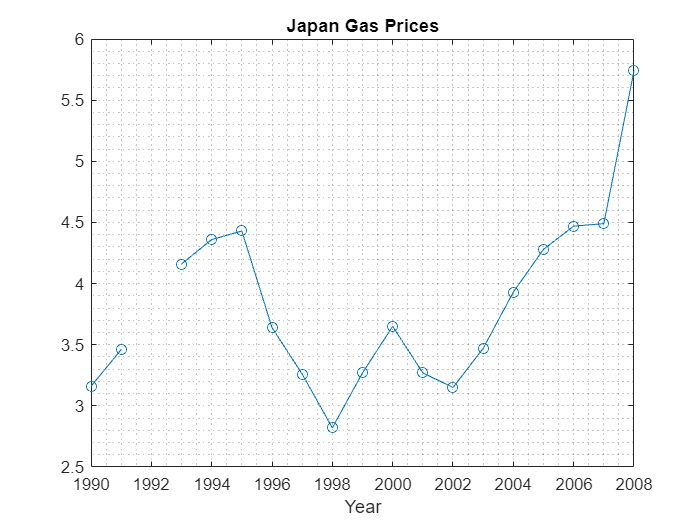

plot(Year,ctryPrices, "o-")
grid minor;
xlabel("Year")
title(ctry + " Gas Prices")

## Analysis Complete Message

Inform user of the other countries that can be visualized.

cmpltMsg = "You can also enter the following countries: " ...
    + join(countries(~idxVec));
disp(cmpltMsg)

You can also enter the following countries: Australia Canada France Germany Italy Mexico South Korea UK USA
